%reading the audio file
[a fs]=audioread("C:\Users\pooja\Desktop\Cryptography\sig100.wav")

a =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


fs = 360


%extracting the first 10 seconds of the audio file
a_cut = a((fs * (10- 1)) + 1 : fs * ( 20- 1), :)

a_cut =    -0.0527   -0.0234
   -0.0537   -0.0293
   -0.0557   -0.0293
   -0.0586   -0.0303
   -0.0586   -0.0312
   -0.0615   -0.0283
   -0.0596   -0.0273
   -0.0586   -0.0283
   -0.0576   -0.0283
   -0.0586   -0.0312





%padding zeros to make a square matrix
a_cut=a

a_cut =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


writematrix(a_cut,"twochannel_og.csv")
%making the 2 channel file a single channel file
a_cut_mono=reshape(a_cut,[],1)

a_cut_mono =    -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0234
   -0.0264


writematrix(a_cut_mono,"OriginalWave.csv")

%finding the factors of the no of rows
n=(size(a_cut_mono))

n =      1300000           1


n=n(1)

n = 1300000

factors=factorList(n);
size(factors)

ans =      1    71





%creating ordered pairs of possible combinations
pairs=combinations(n,factors)

count = 1

pairs =            2      650000
           4      325000
           5      260000
           8      162500
          10      130000
          13      100000
          16       81250
          20       65000
          25       52000
          26       50000



optimal_pair =[pairs(1,:)];
minzero=0;
pairs

pairs =            2      650000
           4      325000
           5      260000
           8      162500
          10      130000
          13      100000
          16       81250
          20       65000
          25       52000
          26       50000


for i = 1:size(pairs,1)/2;
    temppair=[pairs(i,:)];
    temppair(1);
    temppair(2);
    zeroes = optimize(temppair(1), temppair(2));
    zeroes;
    if minzero == 0
        minzero = zeroes;
    else
       if zeroes < minzero
           minzero = zeroes;
           optimal_pair = temppair;
        end
    end
end
minzero

minzero = 262500

temp=optimal_pair(1)

temp = 1040

optimal_pair(1)=optimal_pair(2)

optimal_pair =         1250        1250


optimal_pair(2)=temp

optimal_pair =         1250        1040



a_reshaped=reshape(a_cut,optimal_pair(1),optimal_pair(2))

a_reshaped =    -0.0283   -0.0791   -0.0947   -0.0586   -0.0449   -0.0771   -0.0576   -0.0820    0.0850   -0.0850   -0.0791   -0.0732   -0.1074   -0.0762   -0.0527   -0.0684   -0.0674   -0.0498   -0.0635   -0.0459   -0.0811   -0.0596   -0.0518   -0.0820   -0.0576   -0.0566   -0.0742   -0.0732   -0.0508   -0.0400    0.1670   -0.0928   -0.0723   -0.0713   -0.0879   -0.0596   -0.0664   -0.0889   -0.0684   -0.0801   -0.0752   -0.0684   -0.0605   -0.0674   -0.0439   -0.0674   -0.0605   -0.0557   -0.0732   -0.0615
   -0.0283   -0.0791   -0.0967   -0.0605   -0.0469   -0.0762   -0.0576   -0.0830    0.0127   -0.0840   -0.0791   -0.0742   -0.1162   -0.0791   -0.0547   -0.0674   -0.0693   -0.0479   -0.0615   -0.0176   -0.0830   -0.0586   -0.0518   -0.0840   -0.0557   -0.0537   -0.0732   -0.0732   -0.0488   -0.0400    0.1328   -0.0928   -0.0713   -0.0752   -0.0859   -0.0576   -0.0654   -0.0918   -0.0654   -0.0898   -0.0781   -0.0674   -0.0293   -0.0693   -0.0410   -0.0664   -0.0596   -0.0576   -0.

size(a_reshaped)

ans =         1250        1040


flag=0;
if optimal_pair(1)>optimal_pair(2)
   
    sq_wave = [a_reshaped, zeros(optimal_pair(1),optimal_pair(1)-optimal_pair(2))]
    
else
    a_reshaped=(a_reshaped).'
    size(a_reshaped)
    sq_wave = [a_reshaped, zeros(optimal_pair(2),optimal_pair(2)-optimal_pair(1))]
    flag=1;
    
end

sq_wave =    -0.0283   -0.0791   -0.0947   -0.0586   -0.0449   -0.0771   -0.0576   -0.0820    0.0850   -0.0850   -0.0791   -0.0732   -0.1074   -0.0762   -0.0527   -0.0684   -0.0674   -0.0498   -0.0635   -0.0459   -0.0811   -0.0596   -0.0518   -0.0820   -0.0576   -0.0566   -0.0742   -0.0732   -0.0508   -0.0400    0.1670   -0.0928   -0.0723   -0.0713   -0.0879   -0.0596   -0.0664   -0.0889   -0.0684   -0.0801   -0.0752   -0.0684   -0.0605   -0.0674   -0.0439   -0.0674   -0.0605   -0.0557   -0.0732   -0.0615
   -0.0283   -0.0791   -0.0967   -0.0605   -0.0469   -0.0762   -0.0576   -0.0830    0.0127   -0.0840   -0.0791   -0.0742   -0.1162   -0.0791   -0.0547   -0.0674   -0.0693   -0.0479   -0.0615   -0.0176   -0.0830   -0.0586   -0.0518   -0.0840   -0.0557   -0.0537   -0.0732   -0.0732   -0.0488   -0.0400    0.1328   -0.0928   -0.0713   -0.0752   -0.0859   -0.0576   -0.0654   -0.0918   -0.0654   -0.0898   -0.0781   -0.0674   -0.0293   -0.0693   -0.0410   -0.0664   -0.0596   -0.0576   -0.069



%generating a random key
key=rand(size(sq_wave))

key =     0.8147    0.2859    0.8558    0.1519    0.1689    0.7541    0.3528    0.7643    0.1538    0.8614    0.5538    0.0670    0.2858    0.8189    0.4875    0.7945    0.4362    0.8416    0.5078    0.6492    0.6535    0.3581    0.7649    0.0686    0.8252    0.5779    0.1839    0.5881    0.4995    0.5944    0.6254    0.2571    0.2135    0.6386    0.8091    0.3121    0.1839    0.4785    0.1938    0.1115    0.6254    0.6043    0.1783    0.1251    0.1410    0.6130    0.5360    0.9050    0.6388    0.1687
    0.9058    0.5437    0.6708    0.3807    0.7452    0.5195    0.4002    0.7212    0.9618    0.6578    0.8424    0.7785    0.9312    0.7839    0.5354    0.0608    0.0015    0.3567    0.3943    0.1809    0.6657    0.1906    0.4853    0.6107    0.0908    0.3555    0.9949    0.7776    0.3857    0.3596    0.4775    0.6034    0.9798    0.6108    0.4951    0.2046    0.0488    0.8856    0.4904    0.0259    0.0284    0.8830    0.7045    0.3833    0.5060    0.1394    0.0629    0.0650    0.2237   


%encryption
enc=sq_wave*key

enc =   -24.4002  -25.0997  -25.9072  -25.1187  -24.2892  -24.5312  -24.5918  -24.8988  -25.3108  -24.1480  -24.9947  -24.5266  -25.3248  -24.5769  -25.5138  -24.8335  -23.8363  -25.1631  -24.4163  -24.3128  -24.6211  -24.1783  -24.4953  -23.9475  -25.6843  -25.0844  -25.1750  -24.9701  -23.8772  -25.3118  -23.9726  -23.8215  -24.5116  -23.8587  -25.6953  -24.3642  -24.5502  -25.5779  -24.8409  -23.1778  -24.5771  -24.4158  -24.5383  -24.0173  -24.8926  -23.9777  -24.0089  -24.2201  -24.5293  -24.9989
  -24.3811  -25.0318  -25.8722  -25.1929  -24.3379  -24.4663  -24.6925  -24.7714  -25.4041  -24.1538  -24.8780  -24.6433  -25.4872  -24.4700  -25.5749  -24.6750  -23.7838  -25.1218  -24.5462  -24.1997  -24.7901  -24.0886  -24.4200  -24.0142  -25.5233  -25.1806  -25.0501  -25.0590  -23.9606  -25.3998  -23.9133  -23.8295  -24.4066  -23.7536  -25.7183  -24.3525  -24.5380  -25.5239  -24.7606  -23.2828  -24.6581  -24.4472  -24.4741  -23.9668  -24.9223  -24.0995  -24.1451  -24.2670  -24.4697  -

enc_col=enc(:,1)

enc_col =   -24.4002
  -24.3811
  -24.3191
  -24.1432
  -23.9782
  -23.8991
  -23.8354
  -23.8970
  -23.9290
  -24.0686



enc_stripped=enc(1:1250, 1:1040)

enc_stripped =   -24.4002  -25.0997  -25.9072  -25.1187  -24.2892  -24.5312  -24.5918  -24.8988  -25.3108  -24.1480  -24.9947  -24.5266  -25.3248  -24.5769  -25.5138  -24.8335  -23.8363  -25.1631  -24.4163  -24.3128  -24.6211  -24.1783  -24.4953  -23.9475  -25.6843  -25.0844  -25.1750  -24.9701  -23.8772  -25.3118  -23.9726  -23.8215  -24.5116  -23.8587  -25.6953  -24.3642  -24.5502  -25.5779  -24.8409  -23.1778  -24.5771  -24.4158  -24.5383  -24.0173  -24.8926  -23.9777  -24.0089  -24.2201  -24.5293  -24.9989
  -24.3811  -25.0318  -25.8722  -25.1929  -24.3379  -24.4663  -24.6925  -24.7714  -25.4041  -24.1538  -24.8780  -24.6433  -25.4872  -24.4700  -25.5749  -24.6750  -23.7838  -25.1218  -24.5462  -24.1997  -24.7901  -24.0886  -24.4200  -24.0142  -25.5233  -25.1806  -25.0501  -25.0590  -23.9606  -25.3998  -23.9133  -23.8295  -24.4066  -23.7536  -25.7183  -24.3525  -24.5380  -25.5239  -24.7606  -23.2828  -24.6581  -24.4472  -24.4741  -23.9668  -24.9223  -24.0995  -24.1451  -24.2670  -2

enc_col=reshape(enc_stripped,[],2)

enc_col =   -24.4002  -23.5732
  -24.3811  -23.6308
  -24.3191  -23.7015
  -24.1432  -23.7570
  -23.9782  -23.7833
  -23.8991  -23.8119
  -23.8354  -23.7516
  -23.8970  -23.6512
  -23.9290  -23.4775
  -24.0686  -23.3601


enc_val_col=reshape(enc_stripped,[],1)

enc_val_col =   -24.4002
  -24.3811
  -24.3191
  -24.1432
  -23.9782
  -23.8991
  -23.8354
  -23.8970
  -23.9290
  -24.0686


writematrix(enc_val_col,'EncryptedColumnValues.csv')
writematrix(enc_col,"Encrypted_values.csv")

%decryption
dec=enc*inv(key)

dec =    -0.0283   -0.0791   -0.0947   -0.0586   -0.0449   -0.0771   -0.0576   -0.0820    0.0850   -0.0850   -0.0791   -0.0732   -0.1074   -0.0762   -0.0527   -0.0684   -0.0674   -0.0498   -0.0635   -0.0459   -0.0811   -0.0596   -0.0518   -0.0820   -0.0576   -0.0566   -0.0742   -0.0732   -0.0508   -0.0400    0.1670   -0.0928   -0.0723   -0.0713   -0.0879   -0.0596   -0.0664   -0.0889   -0.0684   -0.0801   -0.0752   -0.0684   -0.0605   -0.0674   -0.0439   -0.0674   -0.0605   -0.0557   -0.0732   -0.0615
   -0.0283   -0.0791   -0.0967   -0.0605   -0.0469   -0.0762   -0.0576   -0.0830    0.0127   -0.0840   -0.0791   -0.0742   -0.1162   -0.0791   -0.0547   -0.0674   -0.0693   -0.0479   -0.0615   -0.0176   -0.0830   -0.0586   -0.0518   -0.0840   -0.0557   -0.0537   -0.0732   -0.0732   -0.0488   -0.0400    0.1328   -0.0928   -0.0713   -0.0752   -0.0859   -0.0576   -0.0654   -0.0918   -0.0654   -0.0898   -0.0781   -0.0674   -0.0293   -0.0693   -0.0410   -0.0664   -0.0596   -0.0576   -0.0693   



a_stripped=dec(1:1250,1:1040)

a_stripped =    -0.0283   -0.0791   -0.0947   -0.0586   -0.0449   -0.0771   -0.0576   -0.0820    0.0850   -0.0850   -0.0791   -0.0732   -0.1074   -0.0762   -0.0527   -0.0684   -0.0674   -0.0498   -0.0635   -0.0459   -0.0811   -0.0596   -0.0518   -0.0820   -0.0576   -0.0566   -0.0742   -0.0732   -0.0508   -0.0400    0.1670   -0.0928   -0.0723   -0.0713   -0.0879   -0.0596   -0.0664   -0.0889   -0.0684   -0.0801   -0.0752   -0.0684   -0.0605   -0.0674   -0.0439   -0.0674   -0.0605   -0.0557   -0.0732   -0.0615
   -0.0283   -0.0791   -0.0967   -0.0605   -0.0469   -0.0762   -0.0576   -0.0830    0.0127   -0.0840   -0.0791   -0.0742   -0.1162   -0.0791   -0.0547   -0.0674   -0.0693   -0.0479   -0.0615   -0.0176   -0.0830   -0.0586   -0.0518   -0.0840   -0.0557   -0.0537   -0.0732   -0.0732   -0.0488   -0.0400    0.1328   -0.0928   -0.0713   -0.0752   -0.0859   -0.0576   -0.0654   -0.0918   -0.0654   -0.0898   -0.0781   -0.0674   -0.0293   -0.0693   -0.0410   -0.0664   -0.0596   -0.0576   -0.

if flag==1
    a_reshaped=(a_reshaped).'
end

a_stripped=reshape(a_stripped,[],1)

a_stripped =    -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0234
   -0.0264


writematrix(a_stripped,'DecryptedValues.csv')

%converting it back into a 2 channel file

orig=reshape(a_stripped,[],2);

%comparison of original file and decrypted file
a_cut

a_cut =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


orig

orig =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


a_cut-orig

ans = 1.0e-10 *

   -0.0305   -0.0084
   -0.0306   -0.0089
   -0.0305   -0.0095
   -0.0309   -0.0098
   -0.0306   -0.0099
   -0.0305   -0.0092
   -0.0301   -0.0090
   -0.0300   -0.0087
   -0.0297   -0.0086
   -0.0299   -0.0090




%plotting the original, encrypted and decrypted waves

%og
t_og=(0:length(a_cut)-1)/fs

t_og = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


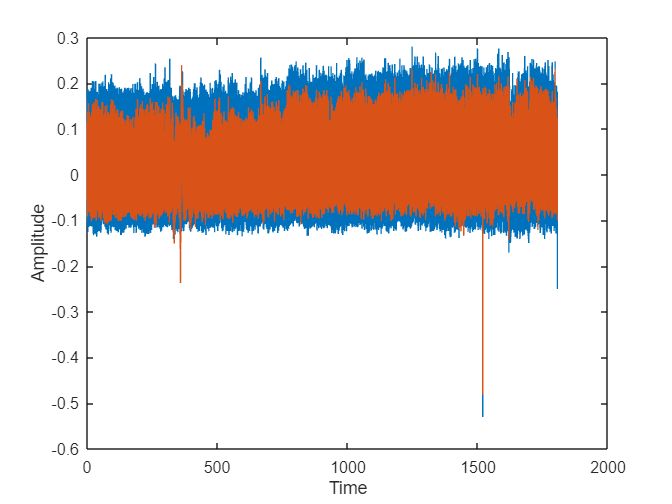

plot(t_og,a_cut)
xlabel("Time")
ylabel("Amplitude")

%encrypted mono channel waveform
t_enc=(0:length(enc_col)-1)/fs

t_enc = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


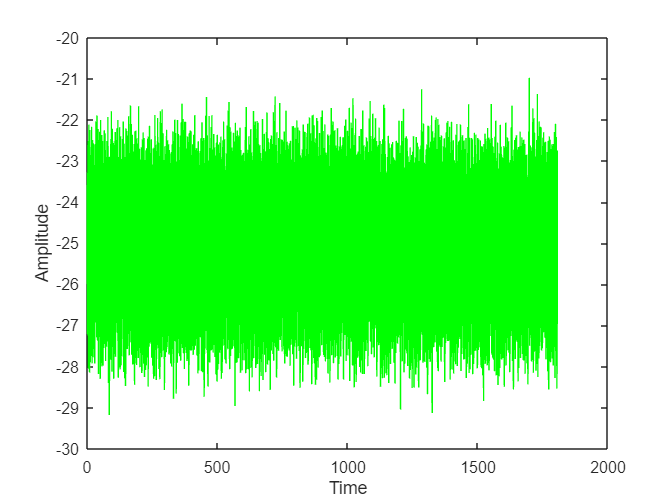

plot(t_enc,enc_col,'g')
xlabel("Time")
ylabel("Amplitude")



%original 2 channel waveform

t_og=(0:length(a_cut)-1)/fs

t_og = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


plot(t_og,a_cut)
xlabel("Time")
ylabel("Amplitude")
hold on 
%decrypted 2 channel waveform
t_dec=(0:length(orig)-1)/fs

t_dec = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


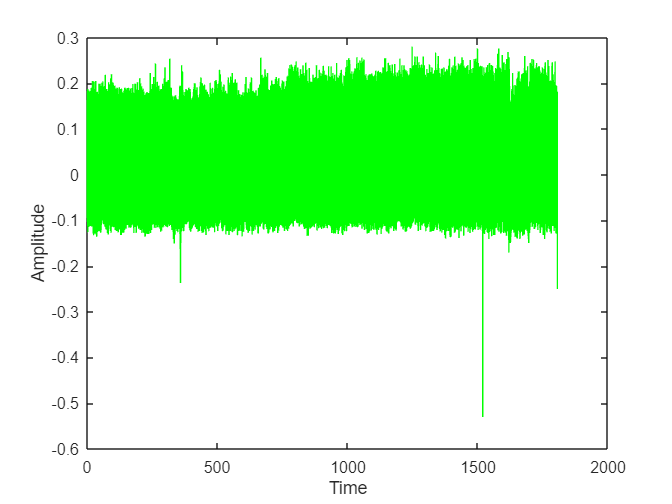

plot(t_dec,orig, 'g')
xlabel("Time")
ylabel("Amplitude")
hold off